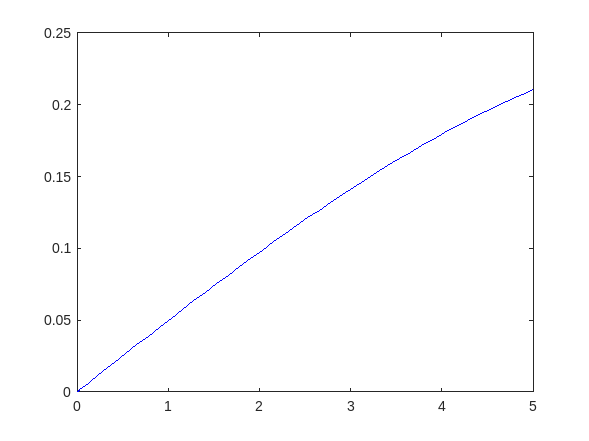

%x = ones(16,1);
x = [ones(8, 1); zeros(8, 1)];
%x = [ones(8, 1); -ones(8, 1)];
[tout, yout] = simTrajectory(x);
figure
plot(tout, yout(:,1), 'b-');

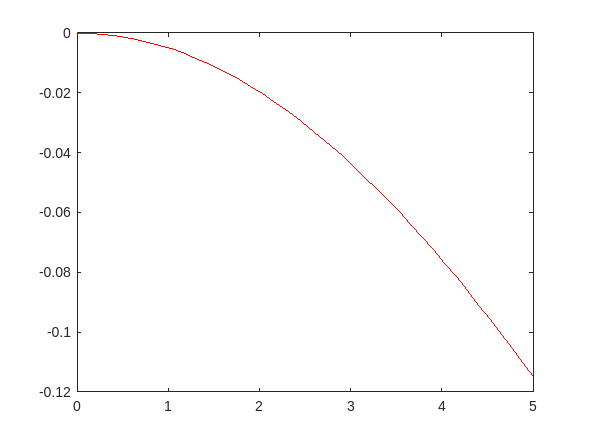

plot(tout, yout(:,2), 'r-');

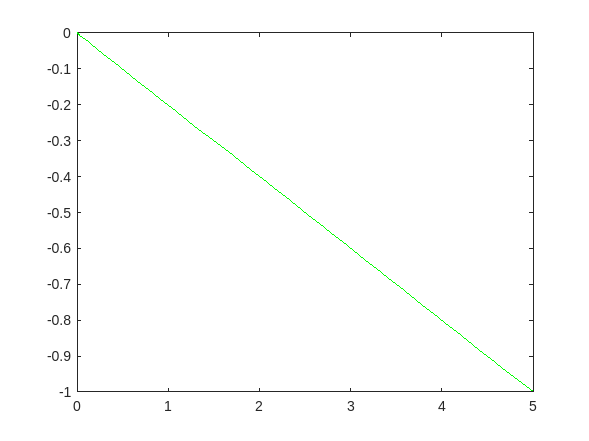

plot(tout, yout(:,3), 'g-');

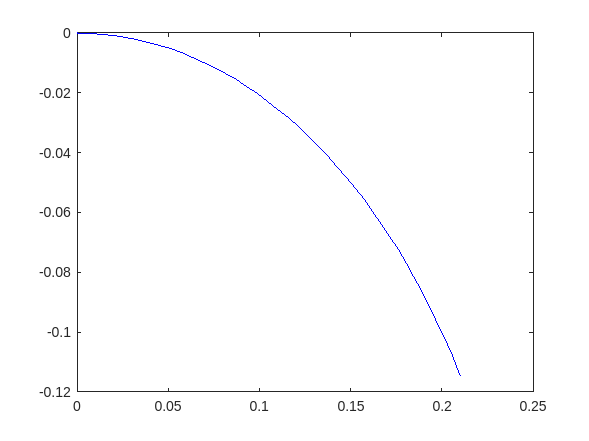

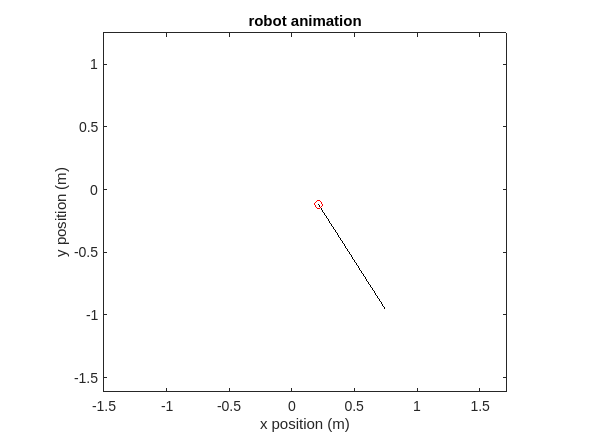

plot(yout(:,1), yout(:,2), 'b-');
animate_robot(tout, yout)

function animate_robot(ts, ys)
    FPS = 20;

    % make time sequence
    t_anim = 0:1/FPS:ts(end);

    % interpolate x, y, theta at each frame
    x_anim = interp1(ts, ys(:, 1), t_anim);
    y_anim = interp1(ts, ys(:, 2), t_anim);
    theta_anim = interp1(ts, ys(:,3), t_anim);

    subplot(2,2,1:4)
    for iter = 1:numel(t_anim) % Animation loop
        cla
        hold on
        title('robot animation')
        arrow = [0 0; cos(theta_anim(iter)) sin(theta_anim(iter))];

        % Plot the direction arrow
        plot(arrow(:, 1) + x_anim(iter), arrow(:, 2) + y_anim(iter), 'k-')
        % Plot the robot
        plot(x_anim(iter), y_anim(iter), 'ro')

        hold off
        axis equal
        axis([min(ys(:,1))-1.5 max(ys(:,1))+1.5 min(ys(:,2))-1.5 max(ys(:,2)) + 1.25])
        xlabel('x position (m)')
        ylabel('y position (m)')
        % Forces the animation to plot mid-loop
        drawnow
    end
end